# Matlab 自带 PSO (只能求fmin)

## 定义自变量个数与定义域

nvars = 2; % 自变量个数
x_lb = [-15 -15];
x_ub = [15 15];

## 求解 Obj_fun 函数

[x, fval, exitflag, output] = particleswarm(@Obj_fun, nvars, x_lb, x_ub);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


## 绘制最佳的函数值随迭代次数的变化图

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


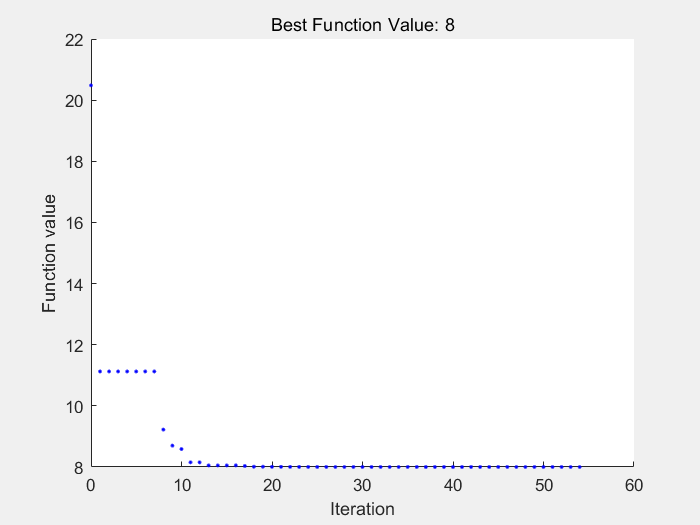

options = optimoptions("particleswarm", "PlotFcn", "pswplotbestf");
[x, fval, exitflag, output] = particleswarm(@Obj_fun, narvs, x_lb, x_ub, options);

## 展示函数迭代过程

options = optimoptions("particleswarm","Display","iter");
[x, fval, exitflag, output] = particleswarm(@Obj_fun, nvars, x_lb, x_ub, options);


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              20           13.06           172.4        0
    1              40           13.06             387        0
    2              60           13.06           169.2        1
    3              80           9.277           152.7        0
    4             100           8.875           129.6        0
    5             120           8.875           159.9        1
    6             140           8.575           94.48        0
    7             160           8.575           137.6        1
    8             180           8.575           104.9        2
    9             200           8.575           159.4        3
   10             220           8.066           88.56        0
   11             240           8.066           143.8        1
   12             260           8.066           99.84        2
   13             280           8.066           

## 修改粒子数量

% 默认为 min(100, 10*nvars)
options = optimoptions("particleswarm","SwarmSize", 50);
[x, fval, exitflag, output] = particleswarm(@Obj_fun, nvars, x_lb, x_ub, options);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


## 算法结束后调用其他函数混合求解

% 算法结束后调用 fmincon 继续求解
options = optimoptions("particleswarm","HybridFcn","fmincon");
[x, fval, exitflag, output] = particleswarm(@Obj_fun, nvars, x_lb, x_ub, options);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


## 设置最大迭代次数

options = optimoptions("particleswarm","MaxIterations", 1000);
[x, fval, exitflag, output] = particleswarm(@Obj_fun, nvars, x_lb, x_ub, options);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


## 邻域内粒子比例

% 默认 0.25
options = optimoptions("particleswarm","MinNeighborsFraction", 0.2);
[x, fval, exitflag, output] = particleswarm(@Obj_fun, nvars, x_lb, x_ub, options);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


## 函数容忍度

% 默认1e-6
options = optimoptions("particleswarm","FunctionTolerance", 1e-8);
[x, fval, exitflag, output] = particleswarm(@Obj_fun, nvars, x_lb, x_ub, options);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


## 最大停滞迭代次数

% 默认20
options = optimoptions("particleswarm","MaxStallIterations", 30);
[x, fval, exitflag, output] = particleswarm(@Obj_fun, nvars, x_lb, x_ub, options);

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


## 上述 options 可叠加在 同一个 options中

% 如：
options = optimoptions("particleswarm","MaxStallIterations", 30,"FunctionTolerance",1e-8);

## 函数定义

function y = Obj_fun(x)
    y = x(1)^2 + x(2)^2 - x(1)*x(2) - 10*x(1) - 4*x(2) + 60;
    % 可考虑增加惩罚项 来构造约束条件
end